clear all;

roots([1 -8 15])

ans =      5
     3


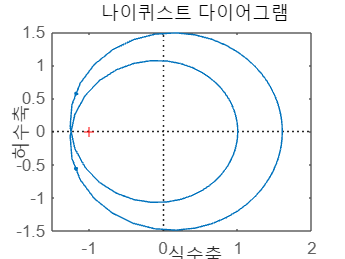

s = tf('s');
G = (s^2 + 10*s +24)/(s^2 - 8*s + 15);
nyquist(G)

isstable(feedback(G,1))

ans = logical
   1


K = 1.3;
G = K*(s^2 + 10*s +24)/(s^2 - 8*s + 15);
f1 = figure;
isstable(feedback(G,1))

ans = logical
   1


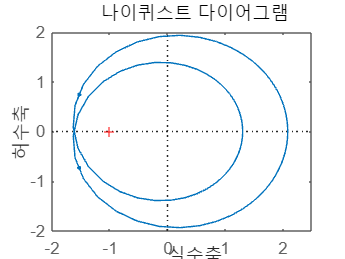

nyquist(G)

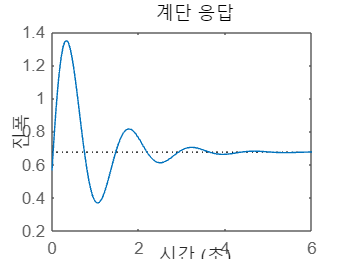


f2 = figure;
step(feedback(G,1))

clf()

clearvars;
s = tf('s');
K = 5;
G = K*50/(s^3 + 9*s^2 + 30*s + 40)

G =
 
            250
  -----------------------
  s^3 + 9 s^2 + 30 s + 40
 
연속시간 전달 함수입니다.
모델 속성


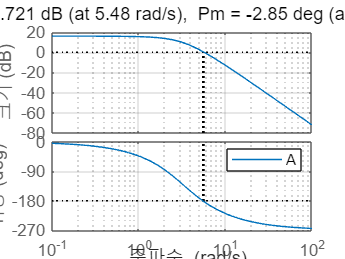

f3 = figure;
margin(G)
grid;
legend('A')

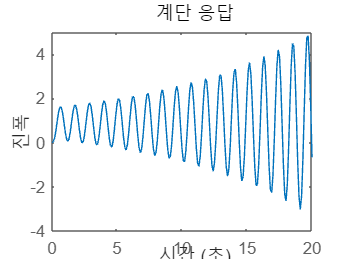


clf();
t = [0:0.1:20];
f4 = figure;
step(feedback(G,1),t)

isstable(feedback(G,1))

ans = logical
   0
